Reading Sorted Global Population Dataset

data1=readtable('C:\Users\S.K.ESWARSUDHAN\Desktop\misproject\glo1.csv');
data=table2array(data1(2:151,3:end-1))

data = 	1.0e+09 *

    0.6671    0.6603    0.6658    0.6823    0.6984    0.7152    0.7354    0.7546    0.7745    0.7960    0.8183    0.8411    0.8620    0.8819    0.9003    0.9164    0.9307    0.9435    0.9562    0.9690    0.9812    0.9939    1.0086    1.0233    1.0368    1.0510    1.0668    1.0840    1.1016    1.1186    1.1352    1.1508    1.1650    1.1784    1.1918    1.2049    1.2175    1.2301    1.2419    1.2527    1.2626    1.2718    1.2804    1.2884    1.2961    1.3037    1.3110    1.3179    1.3247    1.3313
    0.4460    0.4564    0.4670    0.4779    0.4891    0.5001    0.5110    0.5220    0.5334    0.5453    0.5575    0.5700    0.5828    0.5961    0.6097    0.6235    0.6375    0.6517    0.6663    0.6812    0.6968    0.7129    0.7292    0.7458    0.7629    0.7802    0.7979    0.8157    0.8337    0.8520    0.8705    0.8889    0.9076    0.9264    0.9453    0.9643    0.9833    1.0023    1.0214    1.0405    1.0596    1.0790    1.0983    1.1174    1.1363    1.1546    1.1724    1.1897

Case 1 Input window = 10 Predict size = 4 

r=10; %truncating rank
start=1; %starting point of X matrix
input_window=10; %number of columns in X matrix
predict=4; %number of values to predict
n=5; %number of observation to plot
p=DMD(data,start,input_window,predict,r,1) %calling dmd function

p = 	1.0e+08 *

   7.3758 - 0.0000i   7.5675 - 0.0000i   7.7528 - 0.0000i   7.9962 - 0.0000i
   5.1100 - 0.0000i   5.2191 - 0.0000i   5.3343 - 0.0000i   5.4515 - 0.0000i
   7.1032 + 0.0000i   7.1685 + 0.0000i   7.2333 + 0.0000i   7.2794 + 0.0000i
   2.6478 - 0.0000i   2.7166 - 0.0000i   2.7889 - 0.0000i   2.8636 - 0.0000i
   2.6478 - 0.0000i   2.7166 - 0.0000i   2.7889 - 0.0000i   2.8636 - 0.0000i
   2.6473 - 0.0000i   2.7161 - 0.0000i   2.7884 - 0.0000i   2.8630 - 0.0000i
   2.5861 - 0.0000i   2.6584 - 0.0000i   2.7287 - 0.0000i   2.8008 - 0.0000i
   3.7437 + 0.0000i   3.7703 + 0.0000i   3.7975 + 0.0000i   3.8146 + 0.0000i
   1.5403 - 0.0000i   1.5847 - 0.0000i   1.6314 - 0.0000i   1.6795 - 0.0000i
   2.7856 + 0.0000i   2.8030 + 0.0000i   2.8228 + 0.0000i   2.8352 + 0.0000i




d1=data(:,start+input_window-predict+1:start+input_window);
d2=p(:,:);
err=rmse(d1,d2) %Root mean square error

err = 2.4558e+06

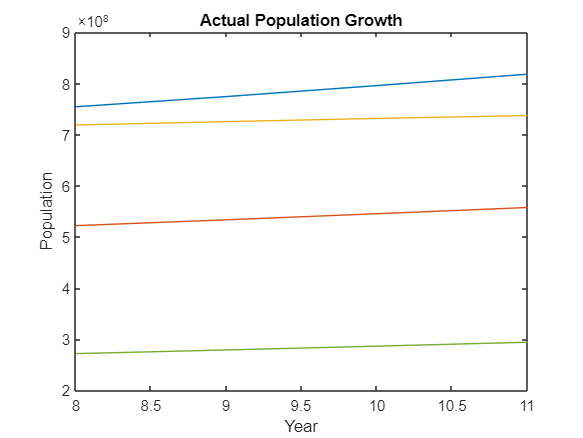


year=start+input_window-predict+1:start+input_window;
%plotting original confirmed cases
plot(year,data(1:n,start+input_window-predict+1:start+input_window)); 
title("Actual Population Growth");
xlabel("Year");
ylabel("Population");


plot(year,p(1:n,:)); %plotting predicted population growth

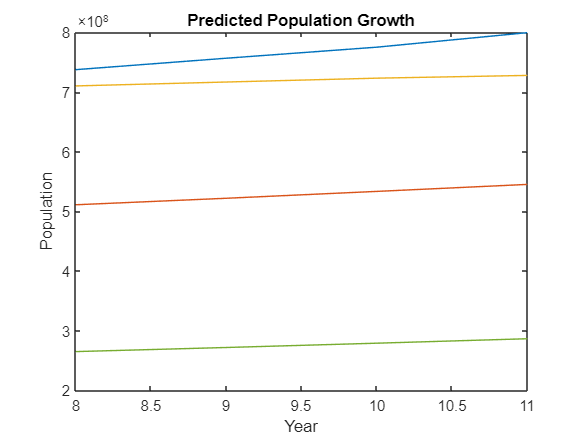

title("Predicted Population Growth");
xlabel("Year");
ylabel("Population");

Case 2 Input window = 20 Predict size = 8

r=10; %truncating rank
start=1; %starting point of X matrix
input_window=20; %number of columns in X matrix
predict=8; %number of values to predict
n=5; %number of observation to plot
p=DMD(data,start,input_window,predict,r,1) %calling dmd function

p = 	1.0e+08 *

   8.6237 - 0.0000i   8.8302 - 0.0000i   9.0203 + 0.0000i   9.1919 + 0.0000i   9.3435 + 0.0000i   9.4758 + 0.0000i   9.5922 + 0.0000i   9.6999 + 0.0000i
   5.8297 - 0.0000i   5.9635 - 0.0000i   6.1004 - 0.0000i   6.2400 + 0.0000i   6.3820 + 0.0000i   6.5260 + 0.0000i   6.6723 + 0.0000i   6.8215 + 0.0000i
   7.4972 - 0.0000i   7.5558 - 0.0000i   7.6126 - 0.0000i   7.6679 - 0.0000i   7.7224 - 0.0000i   7.7769 - 0.0000i   7.8313 - 0.0000i   7.8851 - 0.0000i
   3.1028 + 0.0000i   3.1879 + 0.0000i   3.2764 + 0.0000i   3.3688 - 0.0000i   3.4652 - 0.0000i   3.5656 - 0.0000i   3.6700 - 0.0000i   3.7783 - 0.0000i
   3.1028 + 0.0000i   3.1879 + 0.0000i   3.2764 + 0.0000i   3.3688 - 0.0000i   3.4652 - 0.0000i   3.5656 - 0.0000i   3.6700 - 0.0000i   3.7783 - 0.0000i
   3.1023 + 0.0000i   3.1873 + 0.0000i   3.2759 + 0.0000i   3.3682 - 0.0000i   3.4646 - 0.0000i   3.5649 - 0.0000i   3.6694 - 0.0000i   3.7777 - 0.0000i
   3.0032 + 0.0000i   3.0751 + 0.0000i   3.1483 - 0.0000i   3.2229



d1=data(:,start+input_window-predict+1:start+input_window);
d2=p(:,:);

err=rmse(d1,d2) %Root mean square error

err = 2.4241e+06

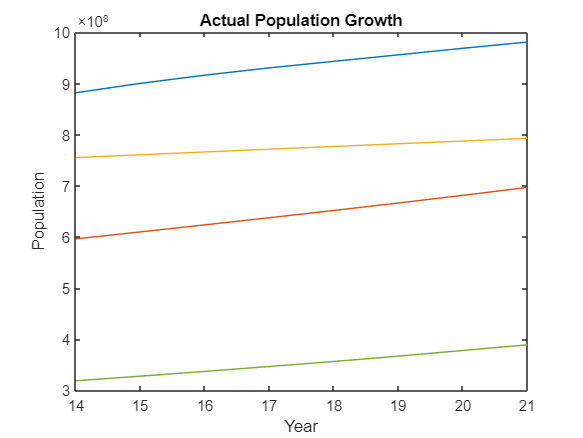


year=start+input_window-predict+1:start+input_window;
%plotting original confirmed cases
plot(year,data(1:n,start+input_window-predict+1:start+input_window)); 
title("Actual Population Growth");
xlabel("Year");
ylabel("Population");


plot(year,p(1:n,:)); %plotting predicted population growth

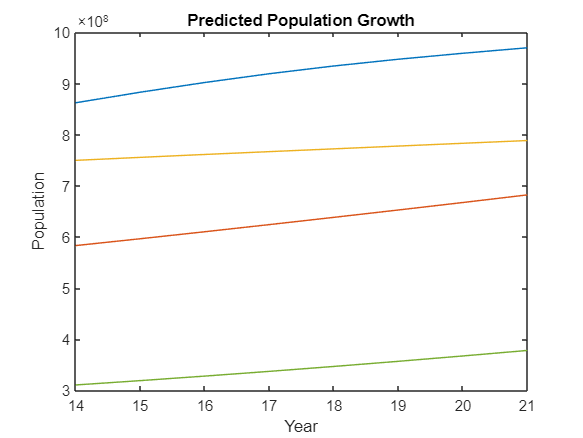

title("Predicted Population Growth");
xlabel("Year");
ylabel("Population");

Case 3 Input window = 20 Predict size = 15

r=10; %truncating rank
start=1; %starting point of X matrix
input_window=20; %number of columns in X matrix
predict=15; %number of values to predict
n=5; %number of observation to plot
p=DMD(data,start,input_window,predict,r,1) %calling dmd function

p = 	1.0e+08 *

   7.1886 + 0.0000i   7.3620 + 0.0000i   7.5435 - 0.0000i   7.7402 - 0.0000i   7.9535 - 0.0000i   8.1779 - 0.0000i   8.4042 - 0.0000i   8.6237 - 0.0000i   8.8302 - 0.0000i   9.0203 + 0.0000i   9.1919 + 0.0000i   9.3435 + 0.0000i   9.4758 + 0.0000i   9.5922 + 0.0000i   9.6999 + 0.0000i
   5.0035 + 0.0000i   5.1125 + 0.0000i   5.2225 + 0.0000i   5.3352 - 0.0000i   5.4520 - 0.0000i   5.5735 - 0.0000i   5.6995 - 0.0000i   5.8297 - 0.0000i   5.9635 - 0.0000i   6.1004 - 0.0000i   6.2400 + 0.0000i   6.3820 + 0.0000i   6.5260 + 0.0000i   6.6723 + 0.0000i   6.8215 + 0.0000i
   7.0521 - 0.0000i   7.1259 - 0.0000i   7.1943 - 0.0000i   7.2575 - 0.0000i   7.3177 - 0.0000i   7.3773 - 0.0000i   7.4373 - 0.0000i   7.4972 - 0.0000i   7.5558 - 0.0000i   7.6126 - 0.0000i   7.6679 - 0.0000i   7.7224 - 0.0000i   7.7769 - 0.0000i   7.8313 - 0.0000i   7.8851 - 0.0000i
   2.5810 - 0.0000i   2.6484 - 0.0000i   2.7185 + 0.0000i   2.7909 + 0.0000i   2.8654 + 0.0000i   2.9420 + 0.0000i   3.0211 + 



d1=data(:,start+input_window-predict+1:start+input_window);
d2=p(:,:);

err=rmse(d1,d2) %Root mean square error

err = 2.4462e+06

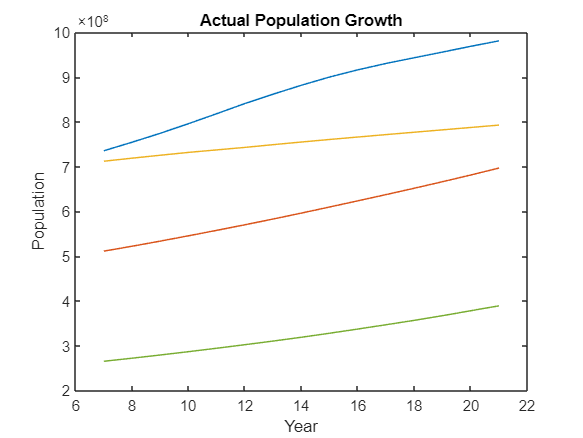


year=start+input_window-predict+1:start+input_window;
%plotting original confirmed cases
plot(year,data(1:n,start+input_window-predict+1:start+input_window)); 
title("Actual Population Growth");
xlabel("Year");
ylabel("Population");


plot(year,p(1:n,:)); %plotting predicted population growth

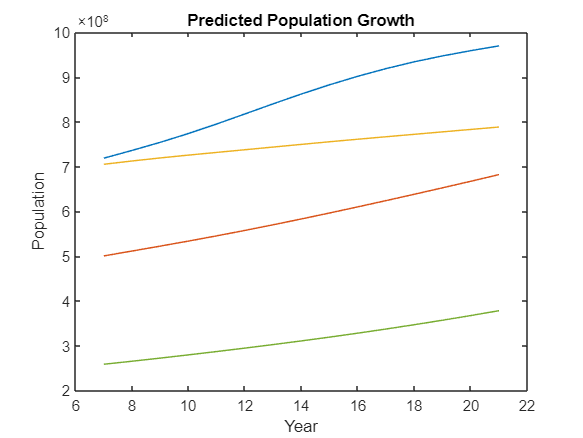

title("Predicted Population Growth");
xlabel("Year");
ylabel("Population");

Comparing Rank vs RMSE

rmse1=[]


rmse1 =

     []



a=30

a = 30

for i=1:a
    r=i; %truncating rank
    start=1; %starting point of X matrix
    input_window=20; %number of columns in X matrix
    predict=15; %number of values to predict
    n=10; %number of observation to plot
    p=DMD(data,start,input_window,predict,r,1); %calling dmd function


    d1=data(:,start+input_window-predict+1:start+input_window);
    d2=p(:,:);

     err=rmse(d1,d2); %Root mean square error
     rmse1=[rmse1 err];
end
rmse1

rmse1 = 	1.0e+06 *

    5.8363    2.7027    2.8293    2.4303    2.4499    2.5125    2.5091    2.4226    2.4289    2.4462    2.4082    2.4975    2.5278    2.4730    2.5996    2.5618    2.5676    2.5887    2.5921    2.7328    3.0291    3.0291    3.0291    3.0291    3.0291    3.0291    3.0291    3.0291    3.0291    3.0291


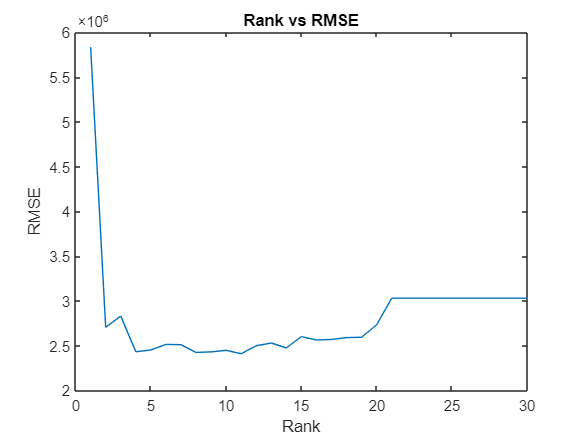

plot([1:a],rmse1)
title("Rank vs RMSE")
xlabel("Rank")
ylabel("RMSE")

Comparing Input Window size vs RMSE

rmse1=[]


rmse1 =

     []



a=40

a = 40

for i=10:a
    r=10; %truncating rank
    start=1; %starting point of X matrix
    input_window=i; %number of columns in X matrix
    predict=5; %number of values to predict
    n=10; %number of observation to plot
    p=DMD(data,start,input_window,predict,r,1); %calling dmd function


    d1=data(:,start+input_window-predict+1:start+input_window);
    d2=p(:,:);

     err=rmse(d1,d2); %Root mean square error
     rmse1=[rmse1 err];
end
rmse1

rmse1 = 	1.0e+06 *

    2.4154    2.5576    2.6152    2.6353    2.6591    2.1937    2.5512    2.5201    3.3720    2.5254    2.3998    2.4850    2.4783    2.4984    2.5634    2.6462    2.7166    2.9344    2.9529    3.0100    3.1516    3.0977    3.1649    3.0587    3.1676    3.2330    3.2025    3.1809    3.1844    3.2052    3.2327


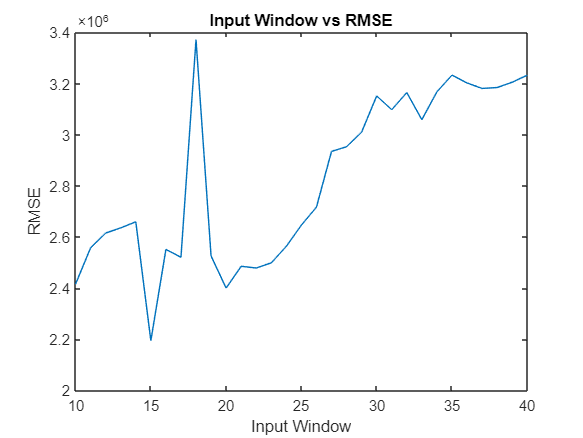

plot([10:a],rmse1)
title("Input Window vs RMSE")
xlabel("Input Window")
ylabel("RMSE")

Comparing Prediction window size vs RMSE

rmse1=[]


rmse1 =

     []



a=20

a = 20

for i=1:a
    r=10; %truncating rank
    start=1; %starting point of X matrix
    input_window=30; %number of columns in X matrix
    predict=i; %number of values to predict
    n=10; %number of observation to plot
    p=DMD(data,start,input_window,predict,r,1); %calling dmd function


    d1=data(:,start+input_window-predict+1:start+input_window);
    d2=p(:,:);

     err=rmse(d1,d2); %Root mean square error
     rmse1=[rmse1 err];
end
rmse1

rmse1 = 	1.0e+06 *

    3.3594    3.3092    3.2633    3.2106    3.1516    3.0995    3.0602    3.0336    3.0070    2.9735    2.9422    2.9147    2.8877    2.8649    2.8484    2.8350    2.8223    2.8077    2.7916    2.7749


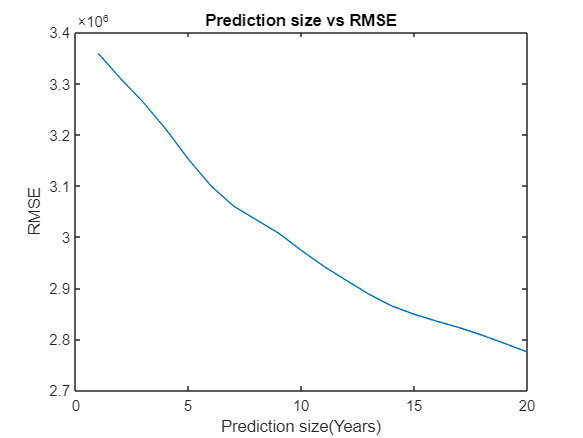

plot([1:a],rmse1)
title("Prediction size vs RMSE")
xlabel("Prediction size(Years)")
ylabel("RMSE")

function  pred = DMD(Xaug,start,m,l,r,dt)
    X = Xaug(:,start:start+m );
    Y = Xaug(:,start+1:start+m+1);
    % SVD and truncate to first r modes
    [U, S, V] = svd(X, "econ" );
    
    r = min(r, size(U,2));
    
    U_r = U(:, 1:r); %truncate to rank-r
    S_r = S(1:r, 1:r);
    V_r = V(:, 1:r);
    
    Atilde = U_r'*Y*V_r/S_r; % Low-rank dynamics
    
    [W_r , D] = eig(Atilde);
    
    Phi = Y * V_r /S_r * W_r;  % DMD modes 
    lambda = diag(D); % discrete-time eigenvalues
    omega = log(lambda)/dt;  % continuous-time eigenvalues

    x1 = X(:, 1); %X0
    b = Phi\x1;
    
    mm1 = size(X, 2); % mm1 = m - 1 
    time_dynamics = zeros(r, mm1);
    t = (0:mm1 -1)*dt; % time vector
    for iter = 1:mm1
        time_dynamics(:,iter) = (b.*exp(omega*t(iter)));
    end 
    Xdmd = Phi * time_dynamics ;

    pred = Xdmd(:,m-l+1:m);
    

end

function rmse = rmse(a,b) %Root Mean Square Error
   D = abs(a-b).^2;
   rmse = sqrt(sum(D(:))/numel(a));
end

